**Design af FIR-filter og støjreduktion af morsesignal:**

help audioread

 audioread Read audio files
    [Y, FS]=audioread(FILENAME) reads an audio file specified by the
    character vector or string scalar FILENAME, returning the sampled data
    in Y and the sample rate FS, in Hertz.
    
    [Y, FS]=audioread(FILENAME, [START END]) returns only samples START 
    through END from each channel in the file.
    
    [Y, FS]=audioread(FILENAME, DATATYPE) specifies the data type format of
    Y used to represent samples read from the file.
    If DATATYPE='double', Y contains double-precision normalized samples.
    If DATATYPE='native', Y contains samples in the native data type
    found in the file.  Interpretation of DATATYPE is case-insensitive and
    partial matching is supported.
    If omitted, DATATYPE='double'.  
    
    [Y, FS]=audioread(FILENAME, [START END], DATATYPE);
 
    Output Data Ranges
    Y is returned as an m-by-n matrix, where m is the number of au

[y, Fs] = audioread('morse(støj).wav');

help sound

 sound Play vector as sound.
    sound(Y,FS) sends the signal in vector Y (with sample frequency
    FS) out to the speaker on platforms that support sound. Values in
    Y are assumed to be in the range -1.0 <= y <= 1.0. Values outside
    that range are clipped.  Stereo sounds are played, on platforms
    that support it, when Y is an N-by-2 matrix.
 
    sound(Y) plays the sound at the default sample rate of 8192 Hz.
 
    sound(Y,FS,BITS) plays the sound using BITS bits/sample if
    possible.  Most platforms support BITS=8 or 16.
 
    Example:
      load handel
      sound(y,Fs)
    You should hear a snippet of Handel's Hallelujah Chorus.
 
    See also soundsc, audioplayer.

    Reference page for sound



%sound(y, Fs)

help spectrogram

 spectrogram Spectrogram using a Short-Time Fourier Transform (STFT).
    S = spectrogram(X) returns the short-time Fourier transform of the
    signal specified by vector X in the matrix S. By default, X is divided
    into eight segments with 50% overlap, and each segment is windowed with
    a Hamming window. The number of frequency points used to calculate the
    discrete Fourier transforms is equal to the larger of 256 or the next
    power of two greater than the segment length.
 
    If X cannot be divided exactly into eight segments, X will be
    truncated.
 
    S = spectrogram(X,WINDOW), when WINDOW is a vector, divides X into
    segments of the same length as WINDOW, and then windows each segment
    with the vector specified in WINDOW.  If WINDOW is an integer, the
    function divides X into segments of length equal to that integer value
    and windows each segment with a Hamming window.  If WINDOW is not
    specified

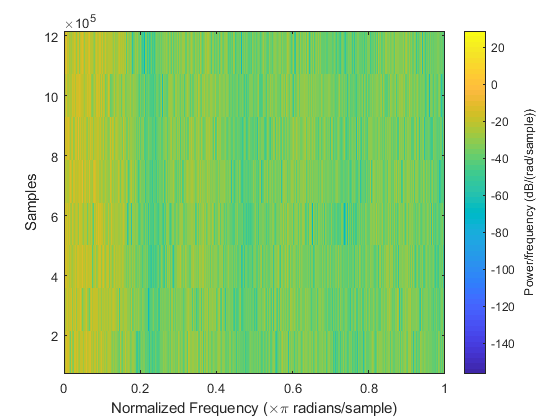

spectrogram(y)


help fir1

 fir1   FIR filter design using the window method.
    B = fir1(N,Wn) designs an N'th order lowpass FIR digital filter
    and returns the filter coefficients in length N+1 vector B.
    The cut-off frequency Wn must be between 0 < Wn < 1.0, with 1.0
    corresponding to half the sample rate.  The filter B is real and
    has linear phase.  The normalized gain of the filter at Wn is
    -6 dB.
 
    B = fir1(N,Wn,'high') designs an N'th order highpass filter.
    You can also use B = fir1(N,Wn,'low') to design a lowpass filter.
 
    If Wn is a two-element vector, Wn = [W1 W2], fir1 returns an
    order N bandpass filter with passband  W1 < W < W2. You can
    also specify B = fir1(N,Wn,'bandpass').  If Wn = [W1 W2],
    B = fir1(N,Wn,'stop') will design a bandstop filter.
 
    If Wn is a multi-element vector,
           Wn = [W1 W2 W3 W4 W5 ... WN],
    fir1<

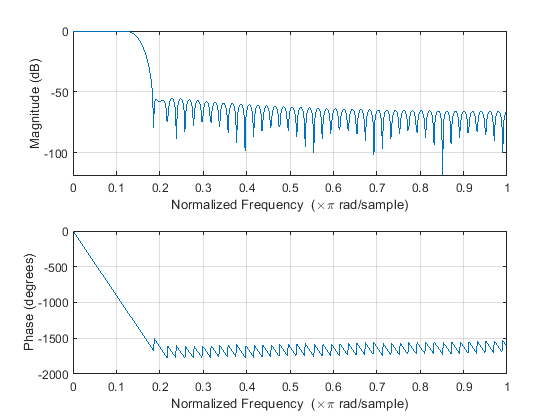

filt = fir1(100,0.15,'low');
freqz(filt)


help filter

 filter One-dimensional digital filter.
    Y = filter(B,A,X) filters the data in vector X with the
    filter described by vectors A and B to create the filtered
    data Y.  The filter is a "Direct Form II Transposed"
    implementation of the standard difference equation:
 
    a(1)*y(n) = b(1)*x(n) + b(2)*x(n-1) + ... + b(nb+1)*x(n-nb)
                          - a(2)*y(n-1) - ... - a(na+1)*y(n-na)
 
    If a(1) is not equal to 1, filter normalizes the filter
    coefficients by a(1). 
 
    filter always operates along the first non-singleton dimension,
    namely dimension 1 for column vectors and non-trivial matrices,
    and dimension 2 for row vectors.
 
    [Y,Zf] = filter(B,A,X,Zi) gives access to initial and final
    conditions, Zi and Zf, of the delays.  Zi is a vector of length
    MAX(LENGTH(A),LENGTH(B))-1, or an array with the leading dimension 
    of size MAX(LENGTH(A),LENGTH(B))-1 

y_filt = filter(filt,1,y);
sound(y_filt,Fs)